## Set up

clc
clear
clf
rng(16);

Preprocessing

Smarket = readtable("Data\Smarket.csv");
Smarket.Direction = categorical(Smarket.Direction);
summary(Smarket);

Variables:

    Var1: 1250×1 double

        Values:

            Min            1  
            Median     625.5  
            Max         1250  

    Year: 1250×1 double

        Values:

            Min         2001  
            Median      2003  
            Max         2005  

    Lag1: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag2: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag3: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag4: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag5: 1250×1 double

        Values:

           

% corrplot(Smarket(:,1:end-1));

## LDA

train = (Smarket.Year < 2005);
Smarket2005 = Smarket(~train,:);
Direction2005 = Smarket.Direction(~train,:);
ldafit = fitcdiscr(Smarket(train, :), 'Direction ~ Lag1 + Lag2');


#### Prior probabilities

array2table(ldafit.Prior, 'VariableNames', cellstr(ldafit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

array2table(ldafit.Mu, 'VariableNames',cellstr(ldafit.ClassNames))

ans = 2×2 table
      Down          Up    
    _________    _________

      0.04279     0.033894
    -0.039546    -0.031325


Predictions

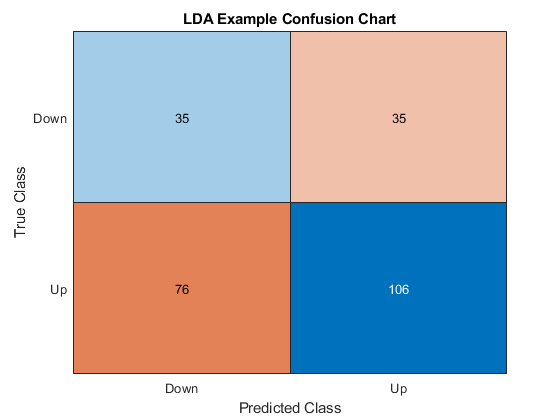

[ldaPredClass, ldaPredPosterior] = predict(ldafit,Smarket2005);
confusionchart(ldaPredClass, Direction2005)
title('LDA Example Confusion Chart');
print('Results/Example/LDA/LDA_confchart', '-dpng', '-r600')

mean(ldaPredClass == Direction2005)

ans = 0.5595

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 70

sum(ldaPredPosterior(:,1) < 0.5)

ans = 182

ldaPredPosterior(1:20,1).'

ans =     0.4902    0.4792    0.4668    0.4740    0.4928    0.4939    0.4951    0.4873    0.4907    0.4844    0.4907    0.5120    0.4895    0.4707    0.4745    0.4800    0.4936    0.5031    0.4979    0.4886


ldaPredClass(1:20,1).'

ans = 1×20 categorical array
     Up      Up      Up      Up      Up      Up      Up      Up      Up      Up      Up      Down      Up      Up      Up      Up      Up      Down      Up      Up 



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 0